[N,C,S] = normalize(lstmdata,"range")

N =          0         0         0         0         0         0
         0         0         0         0    0.4236    0.0041
         0         0         0         0    0.8440    0.0081
         0         0         0         0    0.7585    0.0122
         0         0         0         0    0.6721    0.0163
         0         0         0         0    0.3562    0.0203
         0         0         0         0    0.0432    0.0244
         0         0         0         0    0.0690    0.0285
         0         0         0         0    0.0951    0.0325
         0         0         0         0    0.1490    0.0366


C =      1   120   300     2     0     0


S =     1.0000   20.0000  200.0000    3.0000  139.7696  190.5208


a = S.*N+C

a =     1.0000  120.0000  300.0000    2.0000         0         0
    1.0000  120.0000  300.0000    2.0000   59.2017    0.7745
    1.0000  120.0000  300.0000    2.0000  117.9655    1.5489
    1.0000  120.0000  300.0000    2.0000  106.0220    2.3234
    1.0000  120.0000  300.0000    2.0000   93.9438    3.0979
    1.0000  120.0000  300.0000    2.0000   49.7893    3.8723
    1.0000  120.0000  300.0000    2.0000    6.0367    4.6468
    1.0000  120.0000  300.0000    2.0000    9.6459    5.4213
    1.0000  120.0000  300.0000    2.0000   13.2866    6.1957
    1.0000  120.0000  300.0000    2.0000   20.8318    6.9702


divide2=(0:250:2500)

divide2 =            0         250         500         750        1000        1250        1500        1750        2000        2250        2500


divide1=(1:250:2500)

divide1 =            1         251         501         751        1001        1251        1501        1751        2001        2251


for i = 1:10
    datatrain{i}=N(divide1(i):divide2(i+1),:)'
end

datatrain = 10×1 cell array
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}
    {250×6   double}


datatrain = 10×1 cell array
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {  6×250 double}
    {250×6   double}


datatrain = 10×1 cell array
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}
    {6×250 double}


for n = 1:numel(datatrain)
    X = datatrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(5:6,2:end); % lag XTrain 1 step
end

input = cell(248,6,2);
target = cell(248,2,1);
timestep = 2;
% for i = 1:248
%      input(i,6,i+(timestep-1))={N(i,6),}

% input = cell(248,2);
timestep = 2;
for i = 1:248
input(i,1)={N(i,1:6)}
input(i,2)={N(i+(timestep-1),1:6)}
target(i,1)={N(i+(timestep),5:6)}
end

A(:,:,1)=cell2mat(input(1,1))
A(:,:,2)=cell2mat(input(1,2))
B(:,:,1)=cell2mat(input(1,3))

[N,C,S] = normalize(lstmdata,"range")
a = S.*N+C

for i = 1:248
input(:,i)=N(i,1:6)'
target(1:2,i)=N(i+1,5:6)'
end
% input=input'
% target=target'

input=input'
target=target'

A=cell2mat(input)
A=A'
B=cell2mat(target);
B=B'

numFeatures = 6;
numHiddenUnits = 125;
numResponses = 2;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options);

Error using trainNetwork
Invalid training data. For regression tasks, responses must be a vector, a matrix, or a 4-D array of real numeric responses. Responses must not contain
NaNs.

dlinput = dlarray(input,'CT')
dloutput = dlarray(target,'CT')

Model from Aj. Sompote (Keras)

% model = Sequential()
% model.add(LSTM(50, activation="relu", return_sequences=True, use_bias=True, input_shape=(X_data.shape[1], X_data.shape[2])))
% model.add(LSTM(25, activation="relu"))
% model.add(Flatten())
% model.add(Dense(25))
% #model.add(Flatten())
% model.add(Dense(2))
% model.add(Dense(Y_data.shape[1], activation="tanh"))
% 
% model.summary()

layers = [
    sequenceInputLayer(6)
    lstmLayer(128)
    fullyConnectedLayer(2)
    regressionLayer];

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options);

YTest = predict(net,XTrain,SequencePaddingDirection="left");

Test = YTest{3,1}

Test = 2×249 single matrix
    0.1673    0.3268    0.5154    0.5832    0.5770    0.4642    0.3105    0.2223    0.1719    0.1867    0.2372    0.2293    0.1916    0.1750    0.1700    0.2011    0.2506    0.2435    0.2072    0.1923    0.1897    0.2175    0.2605    0.2512    0.2156    0.2086    0.2172    0.2324    0.2502    0.2426    0.2226    0.2237    0.2358    0.2484    0.2603    0.2604    0.2547    0.2610    0.2730    0.2699    0.2596    0.2604    0.2667    0.2671    0.2644    0.2588    0.2522    0.2504    0.2511    0.2503
    0.0535    0.0742    0.0733    0.0615    0.0473    0.0387    0.0387    0.0421    0.0467    0.0498    0.0506    0.0529    0.0582    0.0645    0.0707    0.0752    0.0773    0.0805    0.0860    0.0919    0.0975    0.1014    0.1031    0.1059    0.1109    0.1158    0.1199    0.1232    0.1258    0.1291    0.1335    0.1377    0.1411    0.1439    0.1464    0.1492    0.1524    0.1554    0.1578    0.1606    0.1642    0.1678    0.1710    0.1743    0.1779    0.1818    0.1861  

FEA = TTrain{1,3}

FEA =     0.4236    0.8441    0.7762    0.7059    0.3784    0.0535    0.0444    0.0368    0.2090    0.3775    0.2251    0.0748    0.0810    0.0890    0.2231    0.3527    0.2112    0.0727    0.0911    0.1117    0.2323    0.3471    0.2152    0.0878    0.1410    0.1939    0.2378    0.2786    0.2094    0.1439    0.1949    0.2450    0.2708    0.2950    0.2724    0.2522    0.2952    0.3352    0.2999    0.2673    0.2960    0.3231    0.3126    0.3018    0.2860    0.2711    0.2779    0.2840    0.2779    0.2716
    0.0041    0.0081    0.0122    0.0163    0.0203    0.0244    0.0284    0.0325    0.0366    0.0406    0.0447    0.0488    0.0528    0.0569    0.0610    0.0650    0.0691    0.0732    0.0772    0.0813    0.0853    0.0894    0.0934    0.0974    0.1015    0.1055    0.1096    0.1136    0.1176    0.1217    0.1257    0.1298    0.1338    0.1378    0.1419    0.1459    0.1499    0.1540    0.1580    0.1621    0.1661    0.1701    0.1741    0.1781    0.1821    0.1861    0.1901    0.1941    0.1981   

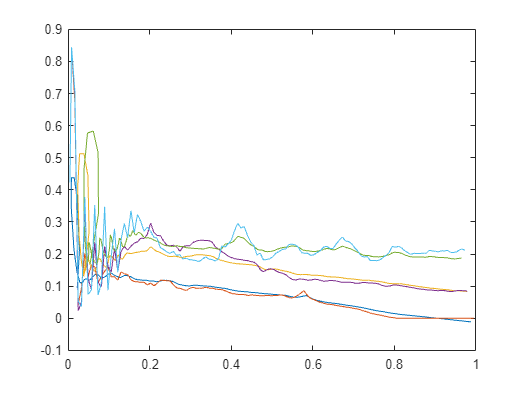

plot(Test(2,:),Test(1,:))
hold on;
plot(FEA(2,:),FEA(1,:))